# Object Detection Using Pretrained YOLO v4 Network

The following code demonstrates running object detection using a pretrained YOLO v4 network, trained on COCO dataset.

## Prerequisites

To run this example you need the following prerequisites - 

- MATLAB (R2021a or later) with Computer Vision and Deep Learning Toolbox.

- Pretrained YOLOv4 network (download instructions below).

## Setup

Add path to the source directory.

addpath('src');

## Download the pre-trained network

This repository uses two variants of YOLO v4 models. **YOLOv4-coco** **YOLOv4-tiny-coco** Set the modelName from the above ones to download that pretrained model.

modelName = 'YOLOv4-coco';
model = helper.downloadPretrainedYOLOv4(modelName);

This can take several minutes to download...
Done.



net = model.net;

## Perform Object Detection Using YOLOv4 Network

Inference is performed on the pretrained YOLOv4 network. Read test image.

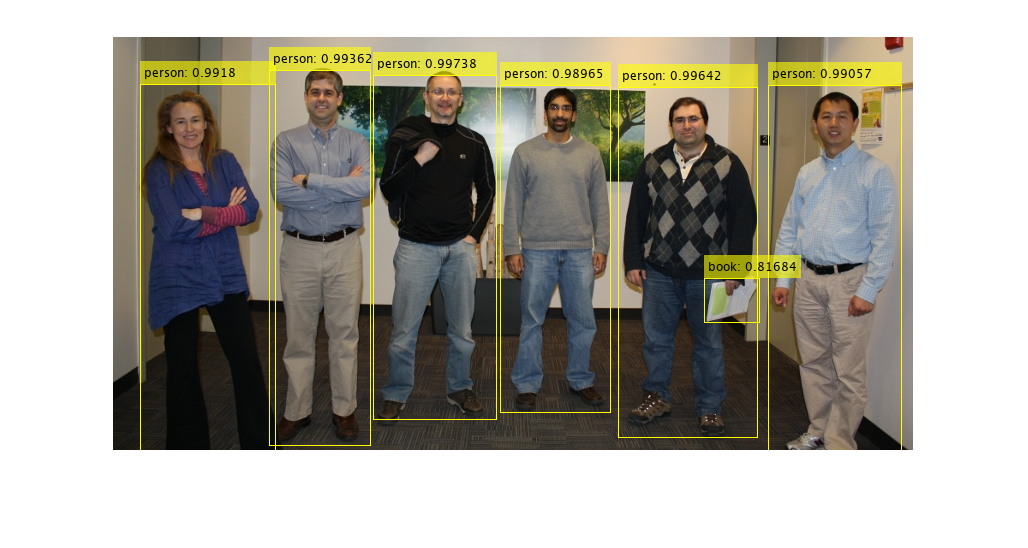

image = imread('visionteam.jpg');

% Get classnames of COCO dataset.
classNames = helper.getCOCOClassNames;

% Get anchors used in training of the pretrained model.
anchors = helper.getAnchors(modelName);

% Detect objects in test image.
executionEnvironment = 'auto';
[bboxes, scores, labels] = detectYOLOv4(net, image, anchors, classNames, executionEnvironment);

% Visualize detection results.
annotations = string(labels) + ": " + string(scores);
image = insertObjectAnnotation(image, 'rectangle', bboxes, annotations);

figure, imshow(image)

*Copyright 2021 The MathWorks, Inc.*